# Muestreo y Cuantización = Discretización

Se propone la siguiente función trigonometrica,para observar los efectos de muestreo y cuantización en una señal con frecuencia de 10 [Hz].

f = 10; %[Hz] = [1/s]


Para observar la señal se propone un vector de tiempo t, con N muestras

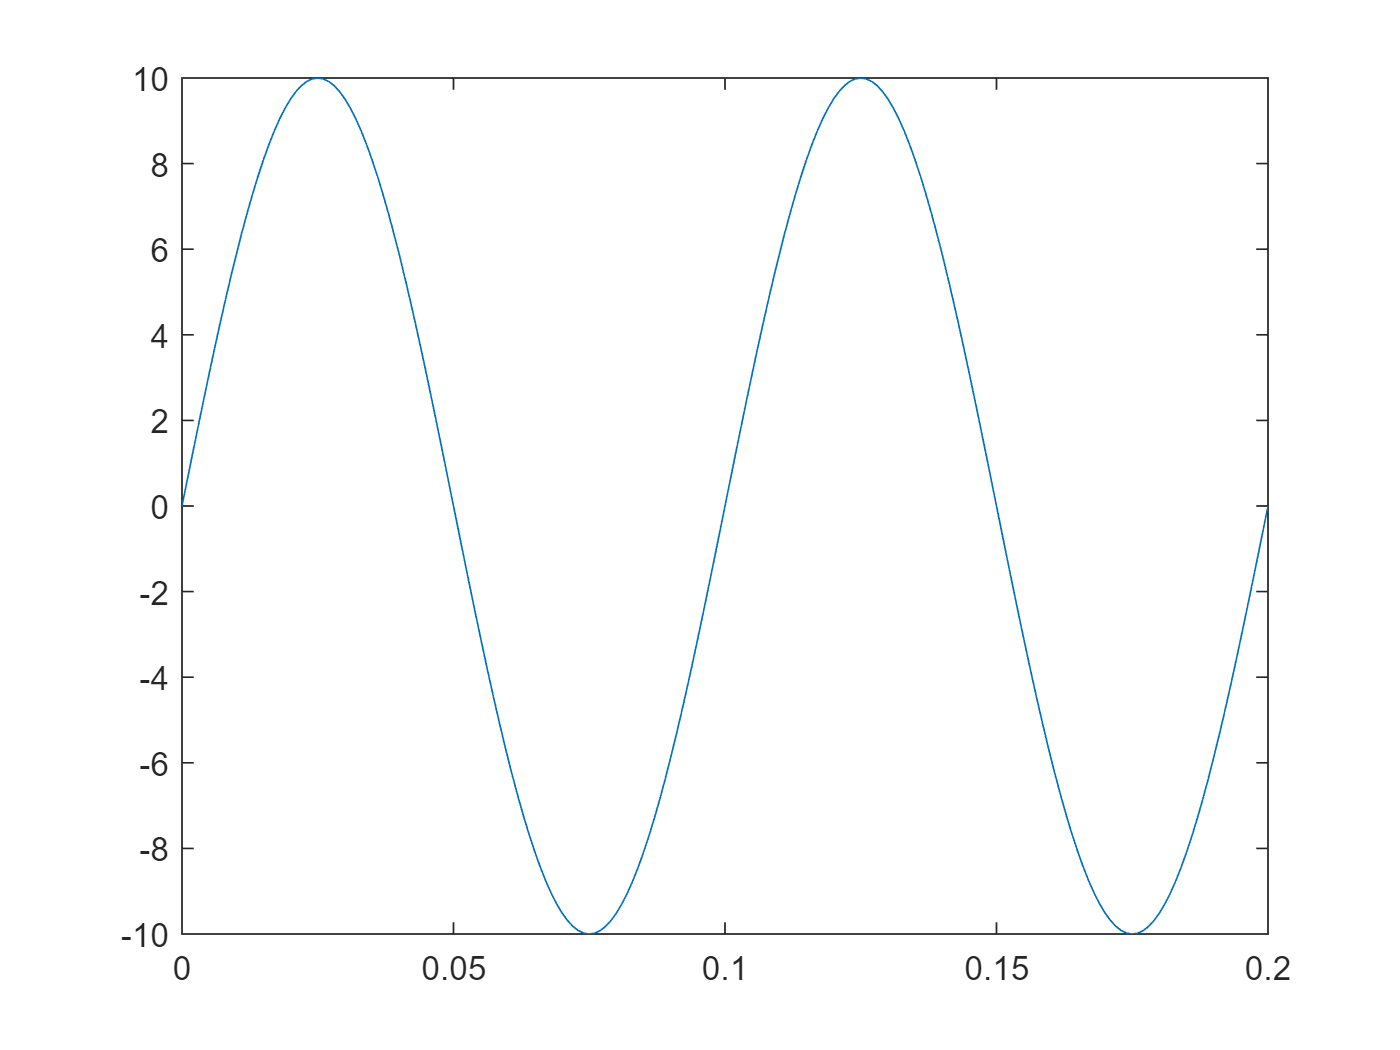

N = 100;
t0 = 0;     %[s]
t1 = 2/f;     %[s]
t = t0: 1/f/N: t1; %[s]

A = 10;
x = A * sin(2*pi*f*t);      % [pi] = rad

% figure(1);
plot(t,x);

## Muestreo

Sabemos que tenemos que muestrear la señal al menos a la frecuencia de Nyquist

f_s >= 2 * f

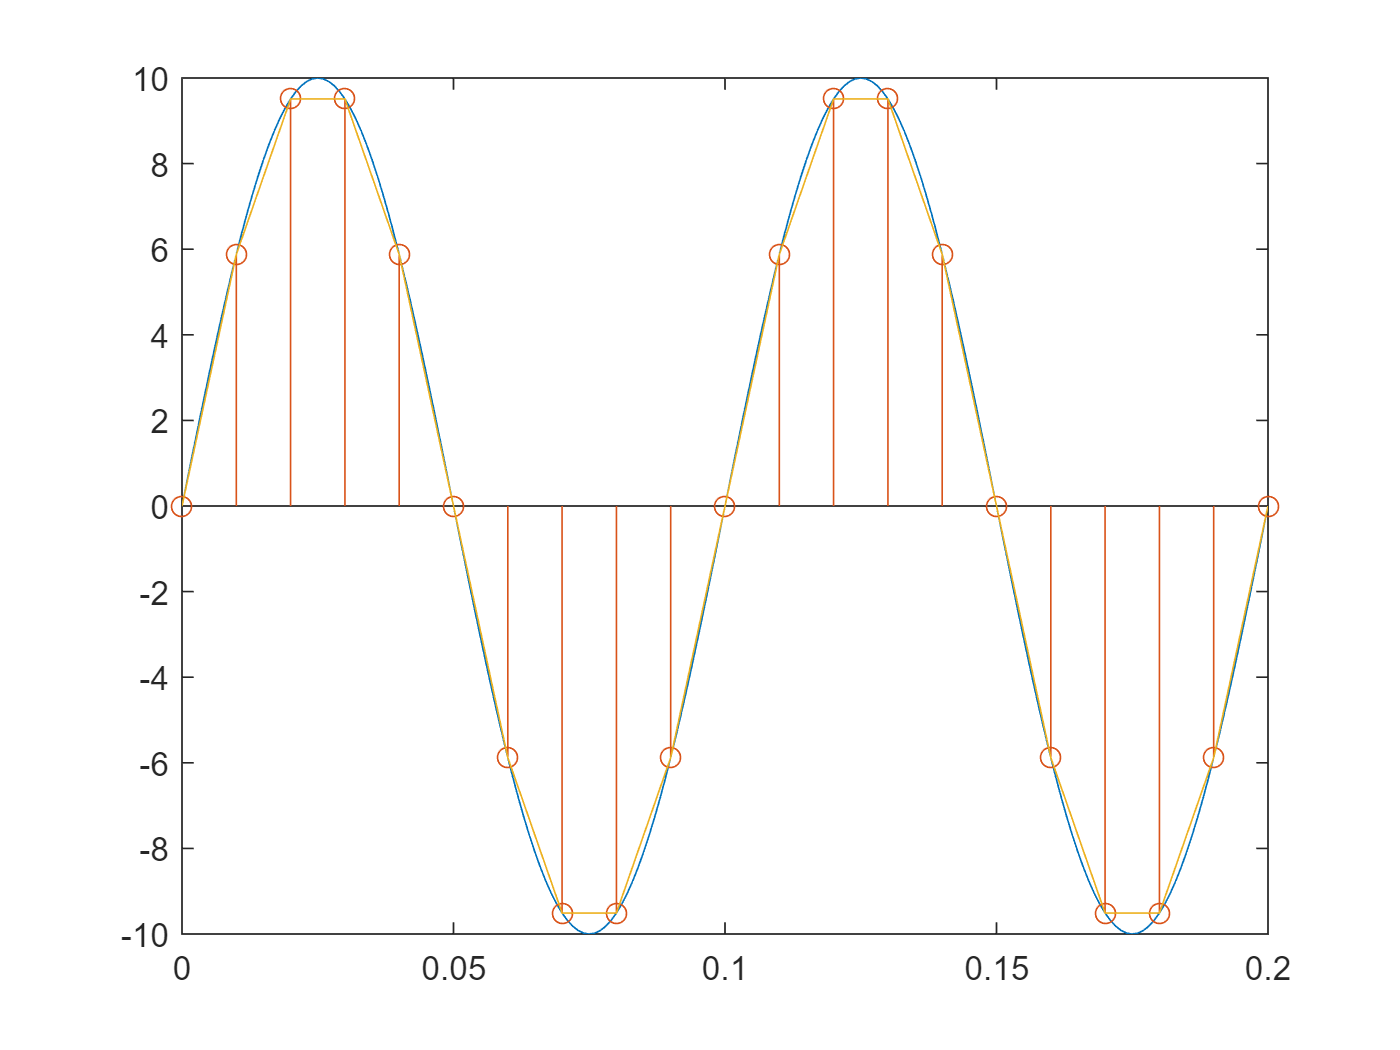

f_s = 10*f;             % tau_s = tau/4
t_s = t0: 1/f_s : t1;

x_s =  A * sin(2*pi*f*t_s);

% x_c = f(x_s, N_c=4)

% hold on;
plot(t,x)
hold on;
stem(t_s, x_s);plot(t_s,x_s);
hold off;

## Cuantización

Propone un parámetro N_c, que me divide la amplitud de mi señal en intervalos del mismo espacio. Además un vector quantos donde se divide ese espacio, para este caso entre [-A, A]

N_c = 5;
quantos = -A: (A - (-A))/(N_c-1) :A

quantos =    -10    -5     0     5    10


A partir del vector muestreado x_s se realiza la cuantización

x_c = f(x_s, quantos)

x(1) = c1

x(45) = c3

x(2:44) = 0

x_c = [];
for i = 1:length(x_s)
    x_s(i)
    aux1 = abs(x_s(i) - quantos)
    [aux2, idx] = min(aux1)
    x_c(i) = quantos(idx) 
end

ans = 0

aux1 =     10     5     0     5    10


aux2 = 0

idx = 3

x_c = 0

ans = 5.8779

aux1 =    15.8779   10.8779    5.8779    0.8779    4.1221


aux2 = 0.8779

idx = 4

x_c =      0     5


ans = 9.5106

aux1 =    19.5106   14.5106    9.5106    4.5106    0.4894


aux2 = 0.4894

idx = 5

x_c =      0     5    10


ans = 9.5106

aux1 =    19.5106   14.5106    9.5106    4.5106    0.4894


aux2 = 0.4894

idx = 5

x_c =      0     5    10    10


ans = 5.8779

aux1 =    15.8779   10.8779    5.8779    0.8779    4.1221


aux2 = 0.8779

idx = 4

x_c =      0     5    10    10     5


ans = 1.2246e-15

aux1 =    10.0000    5.0000    0.0000    5.0000   10.0000


aux2 = 1.2246e-15

idx = 3

x_c =      0     5    10    10     5     0


ans = -5.8779

aux1 =     4.1221    0.8779    5.8779   10.8779   15.8779


aux2 = 0.8779

idx = 2

x_c =      0     5    10    10     5     0    -5


ans = -9.5106

aux1 =     0.4894    4.5106    9.5106   14.5106   19.5106


aux2 = 0.4894

idx = 1

x_c =      0     5    10    10     5     0    -5   -10


ans = -9.5106

aux1 =     0.4894    4.5106    9.5106   14.5106   19.5106


aux2 = 0.4894

idx = 1

x_c =      0     5    10    10     5     0    -5   -10   -10


ans = -5.8779

aux1 =     4.1221    0.8779    5.8779   10.8779   15.8779


aux2 = 0.8779

idx = 2

x_c =      0     5    10    10     5     0    -5   -10   -10    -5


ans = -2.4493e-15

aux1 =    10.0000    5.0000    0.0000    5.0000   10.0000


aux2 = 2.4493e-15

idx = 3

x_c =      0     5    10    10     5     0    -5   -10   -10    -5     0


ans = 5.8779

aux1 =    15.8779   10.8779    5.8779    0.8779    4.1221


aux2 = 0.8779

idx = 4

x_c =      0     5    10    10     5     0    -5   -10   -10    -5     0     5


ans = 9.5106

aux1 =    19.5106   14.5106    9.5106    4.5106    0.4894


aux2 = 0.4894

idx = 5

x_c =      0     5    10    10     5     0    -5   -10   -10    -5     0     5    10


ans = 9.5106

aux1 =    19.5106   14.5106    9.5106    4.5106    0.4894


aux2 = 0.4894

idx = 5

x_c =      0     5    10    10     5     0    -5   -10   -10    -5     0     5    10    10


ans = 5.8779

aux1 =    15.8779   10.8779    5.8779    0.8779    4.1221


aux2 = 0.8779

idx = 4

x_c =      0     5    10    10     5     0    -5   -10   -10    -5     0     5    10    10     5


ans = -1.4090e-14

aux1 =    10.0000    5.0000    0.0000    5.0000   10.0000


aux2 = 1.4090e-14

idx = 3

x_c =      0     5    10    10     5     0    -5   -10   -10    -5     0     5    10    10     5     0


ans = -5.8779

aux1 =     4.1221    0.8779    5.8779   10.8779   15.8779


aux2 = 0.8779

idx = 2

x_c =      0     5    10    10     5     0    -5   -10   -10    -5     0     5    10    10     5     0    -5


ans = -9.5106

aux1 =     0.4894    4.5106    9.5106   14.5106   19.5106


aux2 = 0.4894

idx = 1

x_c =      0     5    10    10     5     0    -5   -10   -10    -5     0     5    10    10     5     0    -5   -10


ans = -9.5106

aux1 =     0.4894    4.5106    9.5106   14.5106   19.5106


aux2 = 0.4894

idx = 1

x_c =      0     5    10    10     5     0    -5   -10   -10    -5     0     5    10    10     5     0    -5   -10   -10


ans = -5.8779

aux1 =     4.1221    0.8779    5.8779   10.8779   15.8779


aux2 = 0.8779

idx = 2

x_c =      0     5    10    10     5     0    -5   -10   -10    -5     0     5    10    10     5     0    -5   -10   -10    -5


ans = -4.8986e-15

aux1 =    10.0000    5.0000    0.0000    5.0000   10.0000


aux2 = 4.8986e-15

idx = 3

x_c =      0     5    10    10     5     0    -5   -10   -10    -5     0     5    10    10     5     0    -5   -10   -10    -5     0


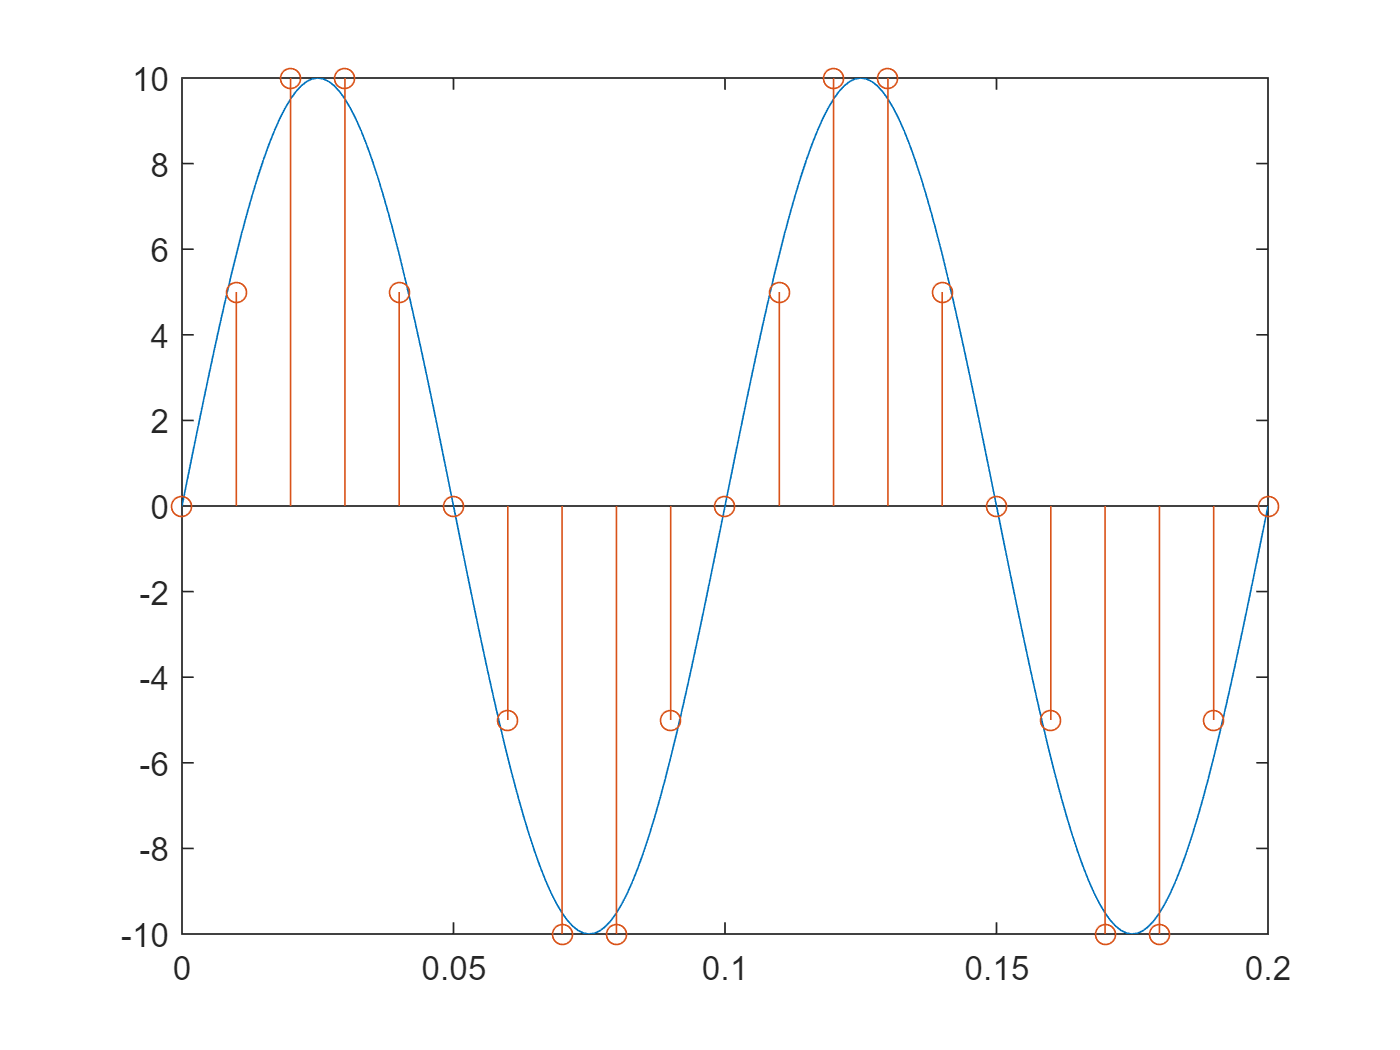


plot(t,x);
hold on;
stem(t_s, x_c);
hold off;